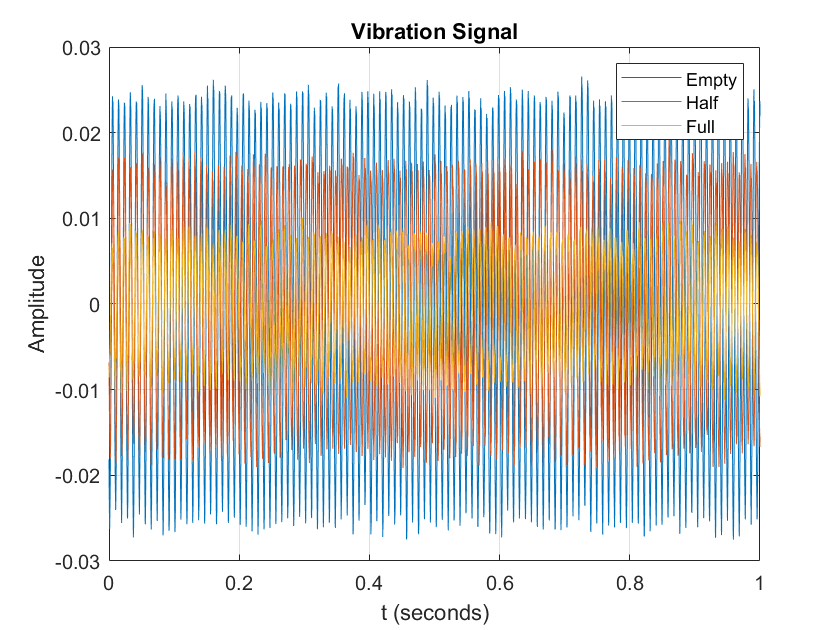

%% Measuring Power
%https://de.mathworks.com/help/signal/ug/practical-introduction-to-frequency-domain-analysis.html
% The |periodogram| function computes the signal's FFT and normalizes the
% output to obtain a power spectral density, PSD, or a power spectrum from
% which you can measure power. The PSD describes how the power of a time
% signal is distributed with frequency, it has units of watts/Hz. You
% compute the power spectrum by integrating each point of the PSD over the
% frequency interval at which that point is defined (i.e. over the
% resolution bandwidth of the PSD). The units of the power spectrum are
% watts. You can read power values directly from the power spectrum without
% having to integrate over an interval. Note that the PSD and power
% spectrum are real, so they do not contain any phase information.

Fs = 100000;          % Sampling frequency (100 kHz)                   
T = 1/Fs;             % Sampling period       
t = 0:T:1-T;        % Time vector

vibration_half = detrend(half_bottle_1); %half.mat
vibration_empty = detrend(empty_bottle_1); %empty.mat
vibration_full = detrend(full_bottle_1); %full.mat

%plot the signal
plot(t,vibration_empty, t, vibration_half, t,vibration_full)
legend('Empty', 'Half', 'Full')
title('Vibration Signal')
xlabel('t (seconds)')
ylabel('Amplitude')
grid on


Fs = 100000; %100 kHz
NFFT = length(vibration_empty); %length of the Signal (FFT Signal Points)


[P,F] = periodogram(vibration_empty,[],NFFT,Fs,'power'); 

[P_half,F_half] = periodogram(vibration_half,[],NFFT,Fs,'power');

[P_full,F_full] = periodogram(vibration_full,[],NFFT,Fs,'power');

%find peaks in empty signal
[pks,locs] = findpeaks(10*log10(P),'MinPeakHeight',-50, 'MinPeakDistance',100)

pks = -37.8046

locs = 111

%find peaks in half full signal
[pks_half,locs_half] = findpeaks(10*log10(P_half),'MinPeakHeight',-50, 'MinPeakDistance',100)

pks_half = -39.5429

locs_half = 112

%find peaks in full signal
[pks_full,locs_full] = findpeaks(10*log10(P_full),'MinPeakHeight',-50, 'MinPeakDistance',100)

pks_full = -45.2107

locs_full = 111


plot (F,10*log10(P),F_half,10*log10(P_half),F_full,10*log10(P_full),'LineWidth',2)

results_empty = 0;
results_half = 0;
results_full = 0;
counter = 0;

if (locs(1,1) > 100) && (locs(1,1) < 150)
    results_empty = pks(1,1)
end

results_empty = -37.8046


if (locs_half(1,1) > 100) && (locs_half(1,1) < 150)
    results_half = pks_half(1,1)
end

results_half = -39.5429


if (locs_full(1,1) > 100) && (locs_full(1,1) < 150)
    results_full = pks_full(1,1)
end

results_full = -45.2107

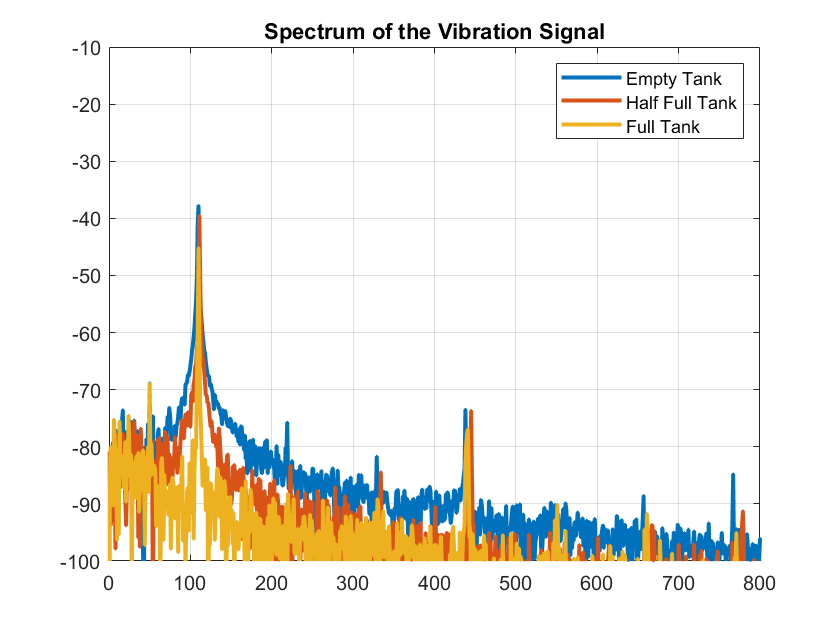


% %calculate the mean of the peaks
% for i = 1:length(pks)
%     if (locs(i,1) < 300) && (locs(i,1) > 100)
%         counter = counter +1;
%         results_empty = results_empty + pks(i,1);
%     end
% end
% results_empty
% counter = 0;
% 
% %calculate the mean of the peaks
% for i = 1:length(pks_half)
%     if (locs_half(i,1) < 300) && (locs_half(i,1) > 100)
%         counter = counter +1;
%         results_half = results_half + pks_half(i,1);
%     end
% end
% results_half
% counter = 0;
% 
% %calculate the mean of the peaks
% for i = 1:length(pks_full)
%     if (locs_full(i,1) < 300) && (locs_full(i,1) > 100)
%         counter = counter +1;
%         results_full = results_full + pks_full(i,1);
%     end
% end
% results_full
% counter = 0;


%plot (F,10*log10(P))
title('Spectrum of the Vibration Signal')
legend('Empty Tank','Half Full Tank', 'Full Tank')
grid on
axis([0 800 -100 -10])


% plot(y,x)
xlabel('dB of Power Spectrum')
ylabel('Fill level in %')

% %plot the signal
t = 0:T:1-T;  % Time vector
% plot(t,detrend(ceramic_piezo))
% hold on
% plot(t,detrend(piezo_foil))
% hold off
% legend('Piezo-Ceramic Sensor','Piezo-Foil Sensor')
% title('Vibration Signal')
% xlabel('t (seconds)')
% ylabel('Amplitude')
% grid on
% 
% plot (F,10*log10(P))
% xlabel('Frequency in Hz')
% ylabel ('Power in dB')
% title('Spectrum of the Vibration Signal')
% legend('Vibration Motor @ 3.3V')
% grid on
% axis([0 800 -100 -10])
% 
% xlim([9 809])
% ylim([-110.9 -20.9])

%y = kx+d